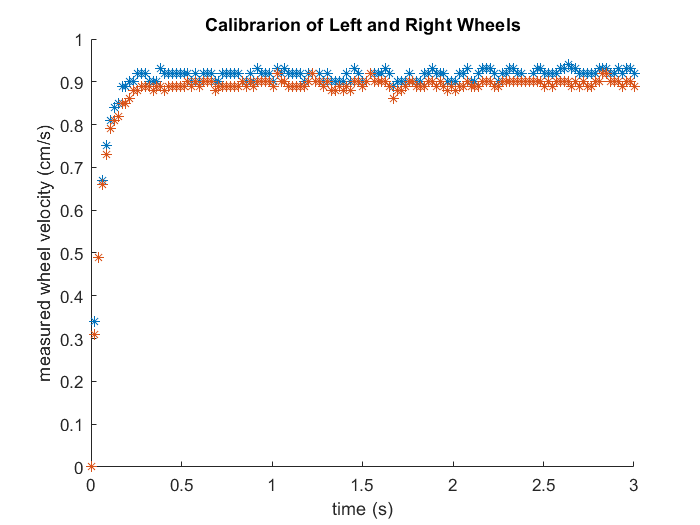

time = linspace(0, 3, 141);
l_wheel = tablerockycalibration(:,1);
r_wheel = tablerockycalibration(:,2);

clf; hold on; 
plot(time, l_wheel, "*");
plot(time, r_wheel, "*");

title("Calibrarion of Left and Right Wheels");
xlabel("time (s)"); ylabel("measured wheel velocity (cm/s)");

Plotting Curve Fitting Data:

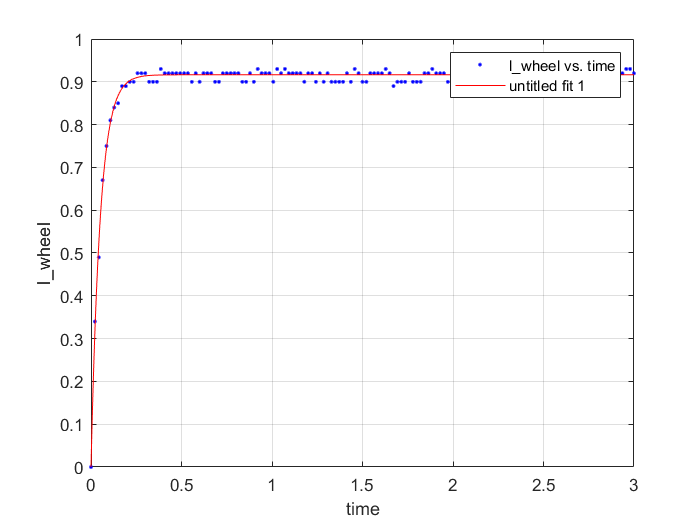

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =       0.051  (0.04932, 0.05268)
       a =      0.9164  (0.9144, 0.9184)

createLWheelFit(time, l_wheel)

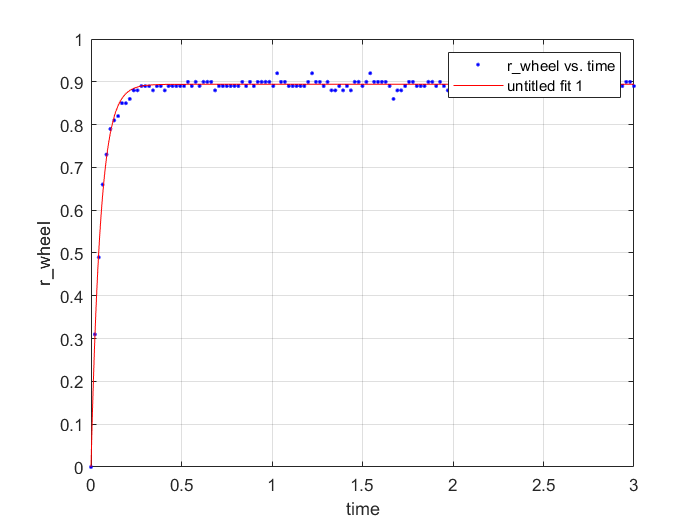

ans =      General model:
     ans(x) = a*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       T =     0.05191  (0.05049, 0.05333)
       a =      0.8942  (0.8926, 0.8958)

createRWheelFit(time, r_wheel)

Frequency Calibration:

clf;
time = 0.05*[1:553]

time =     0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000


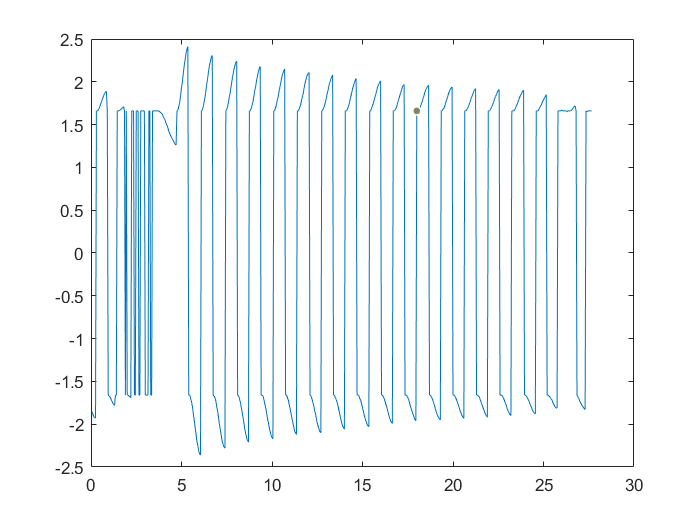

plot(time, FrequencyCalibrarionData)

Functions for Making Curve Fit Plots

function [fitresult, gof] = createLWheelFit(time, l_wheel)
%CREATEFIT(TIME,L_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: l_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:34:30


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, l_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.278498218867048 0.128610587325334];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'l_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'l_wheel', 'Interpreter', 'none' );
grid on

end

function [fitresult, gof] = createRWheelFit(time, r_wheel)
%CREATEFIT(TIME,R_WHEEL)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : time
%      Y Output: r_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 27-Feb-2023 11:37:35


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( time, r_wheel );

% Set up fittype and options.
ft = fittype( 'a*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.546881519204984 0.957506835434298];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'r_wheel vs. time', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time', 'Interpreter', 'none' );
ylabel( 'r_wheel', 'Interpreter', 'none' );
grid on

end